# Tarjeta de Sonido

## Escanear dispositivos de audio

audioInfo=audiodevinfo

audioInfo = struct with fields:
     input: [1×2 struct]
    output: [1×2 struct]


## Crear objeto de audio

Id=-1;
fs=8000; %Frecuencia de muestreo [Hz]
% Audio humano 22KHz  se debe capturar al doble de la fracuencia / Teorema de Nyquist 
CH_No=1; %No. de canales de entrada (Stereo [2] o mono [1])
BitDepth=8; %Profundidad de Bits por muestra

%Default: fs=8kHz, BitDepth bit, 1 CH
recordObject=audiorecorder(fs,BitDepth,CH_No,Id)

recordObject =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


## Grabación

T=3; %Tiempo de grabación [s]
recordblocking(recordObject,T); %Comienza a grabar y reemplazar

## Ploteo

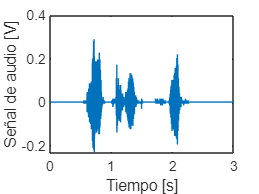

data_grabacion=getaudiodata(recordObject);

%Vector de tiempo
t=1/fs:1/fs:T;
plot(t,data_grabacion)
xlabel("Tiempo [s]")
ylabel("Señal de audio [V]")

## Reproducción

sound(data_grabacion,fs);
%sound(data_grabacion,fs*2);


## Espectro

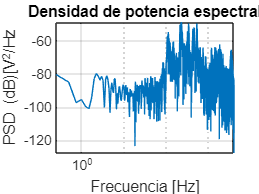

N=numel(data_grabacion); %Numero de muestras de la señal
N_spect=N/50; %Numero de muestras del espectograma

%Funciones de descomposición espectral
[Pxx_Per,F_Pxx]=periodogram(data_grabacion,rectwin(N),[],fs);
[~,F_Spec,T_Spec,Pxx_Spec]=spectrogram(data_grabacion,rectwin(N_spect),[],[],fs);
%Time-Frequency ridge: Busca la oscilación mas fuerteen un espectograma
%fr=tfridge(Pxx_Per,F_Spec);

%Peroidograma
figure
semilogx(F_Pxx,10*log10(Pxx_Per))
title("Densidad de potencia espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD (dB)[V^2/Hz")
grid on

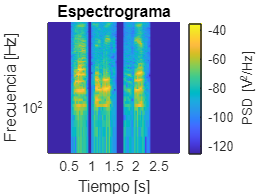


%Espectrograma
figure
p=pcolor(T_Spec,F_Spec,10*log10(Pxx_Spec));
set(p,'EdgeColor','none')
xlabel("Tiempo [s]")
ylabel("Frecuencia [Hz]")
title("Espectrograma")
c=colorbar;
c.Label.String="PSD [V^2/Hz]";
colormap('parula')
set(gca,'YScale','log')

## Sin argumentos de salida

Periodograma y espectrograma deafult

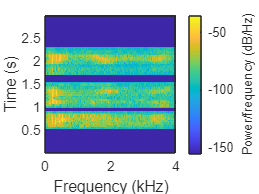

spectrogram(data_grabacion,rectwin(N_spect),[],[],fs)

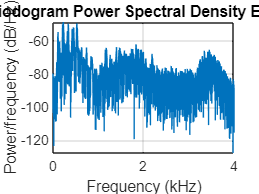


periodogram(data_grabacion,rectwin(N),[],fs)

## Guardar Audio

audiowrite("vozLuis.wav",data_grabacion,fs)


## Git

[https://github.com/LuiSamaniego/digitalizacion2022-1/tree/S4_Estadistica_Audio/Programaci%C3%B3n](https://github.com/LuiSamaniego/digitalizacion2022-1/tree/S4_Estadistica_Audio/Programaci%C3%B3n)